# Example: Acoustics in 2D, Time Series Data

This live-script features the following:

- 2D example

- how to generate time series data

- different visualizations

- visualizing point source and receiver locations

- plotTimeSeries for solutions

In real world applications, the pressure field (or the other fields) is only sampled at a discrete and small number of spatial locations where receivers are placed. Here we give examples on how to simulate data "recorded" at receiver locations.

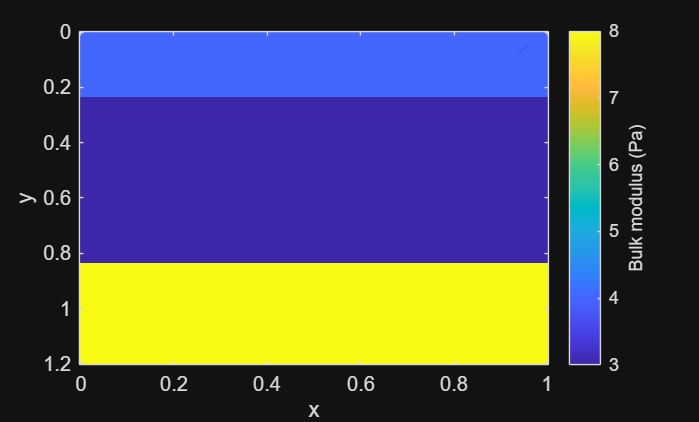

clear

domain_x = [0,1];
domain_y = [0,1.2];
domain_t = [0,1.5];

% Computational grids and grid spaces
Nx = 151;
Ny = 161;

grid_x_primal = Grid1DUnifPrimal(domain_x,Nx);
grid_y_primal = Grid1DUnifPrimal(domain_y,Ny);
grid_x_dual = Grid1DUnifDual(grid_x_primal);
grid_y_dual = Grid1DUnifDual(grid_y_primal);

gridSp_P  = GridSpace2D( grid_x_primal, grid_y_primal);
gridSp_Vx = GridSpace2D( grid_x_dual,   grid_y_primal);
gridSp_Vy = GridSpace2D( grid_x_primal, grid_y_dual);

h = gridSp_P.h;

% Medium parameters
medium = AcousticMedium2D.layeredY( ...
    BetaValues=[0.25,0.5,1], ...
    KappaValues=[4,3,8], ...
    Domain=[domain_x;domain_y], ...
    RelativeWidths=[0.2,0.5,0.3]);
[kappa,betax,betay,wspeed,cMax] = sampleMedium2D(gridSp_P,medium);

kappa.plot;


% Computational time grid
CFL = 0.9;
dt = CFL*(6/7)/(cMax*sqrt(sum(1./h.^2)));
Nt = ceil(diff(domain_t)/dt)+1;
dt = diff(domain_t)/(Nt-1); %recomputing dt to ensure time length is divisible by dt
t_pts = domain_t(1):dt:domain_t(2);

% Output times
t_pts_out = linspace(domain_t(1),domain_t(2),81);

% Initializing PML
pml = PML2D( ...
    WidthLeft=0.15, ...
    WidthRight=0.15, ...
    WidthBottom=0.15, ...
    WidthTop=0.15);

% Zero initial conditions
p0 = @(x,y) zeros(size(x));
vx0 = @(x,y) zeros(size(x));
vy0 = @(x,y) zeros(size(x));

Here we specify a multipole source with two terms centered at different locations.

% Multipole point source
loc0 = [0.9,1];
s0   = [0,0];
w0   = @(t) exp(-(t-0.2).^2/0.025^2);
monopole = MultipoleTerm2D(loc0,s0,w0,TargetField="pressure");

loc1 = [0.85,0.85];
s1   = [1,0];
w1   = @(t) 10*h(1)*RickerWave(t,0.2,10);
dipoleX = MultipoleTerm2D(loc1,s1,w1,TargetField="pressure");

mps = MultipoleSeries2D([monopole,dipoleX]);
source = mps.discretize(gridSp_P,gridSp_Vx,gridSp_Vy);


% Defining grids consisting of points or lines to later construct grid
% spaces for different output configurations
grid_x_pt = Grid1D(domain_x,0.1);
grid_y_pt = Grid1D(domain_y,0.5);
grid_x_line = Grid1DUnifPrimal([0.1,0.5],11);
grid_y_line = Grid1DUnifPrimal([0.5,0.6],3);

Here we specify a single receiver point.

gridSp_single = GridSpace2D(grid_x_pt,grid_y_pt);

The function `plotAcqGeo()` helps visualize how the sources and receiver are located relative to a given grid function, typically a sampled acoustic medium like the wave speed. Assuming the y axis corresponds to depth, with positive y values denoting positive depth, the positive y axis then oriented downwards.

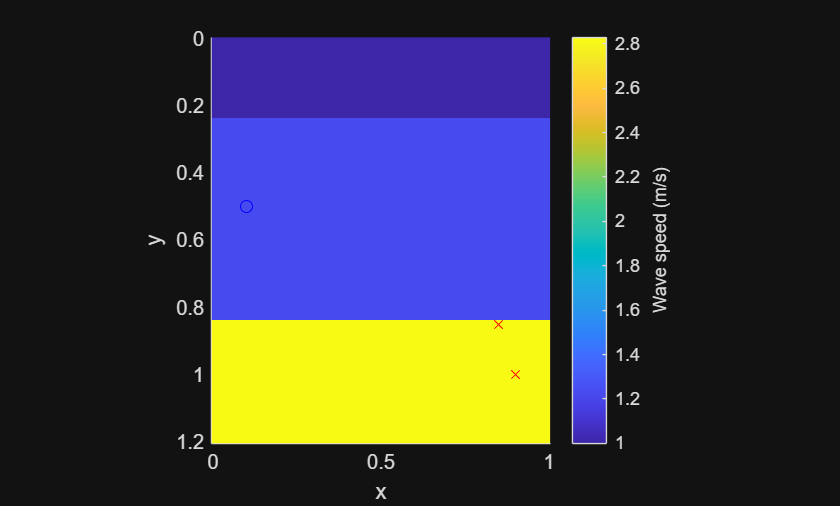

plotAcqGeo(wspeed,mps,gridSp_single);
ax = gca;
ax.YDir = "reverse";
axis(ax,"tight");
axis(ax,"image");

% Initialize solver
solver_single = AcousticSolver2D_PML( ...
    gridSp_P,t_pts, ...
    gridSp_single,t_pts_out, ...
    medium,pml, ...
    SpatialOrder=4);

% Run solver
[P_single,~,~] = solver_single.solve(p0,vx0,vy0,Source=source);

In the case of a single receiver, we visualize the output data as a plot of the field (e.g., pressure) versus time.

P_single.plotTimeSeries;

Here we specify a horizontal line of receivers.

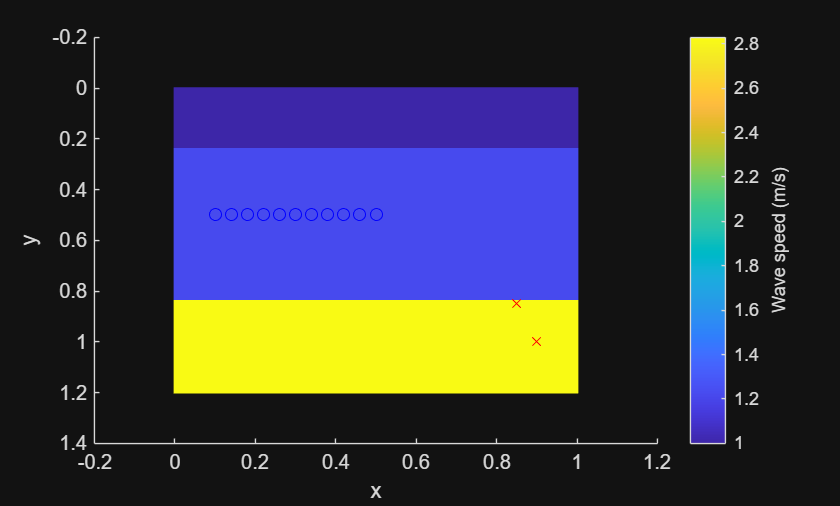

gridSp_x_line = GridSpace2D(grid_x_line,grid_y_pt);

plotAcqGeo(wspeed,mps,gridSp_x_line);
ax = gca;
ax.YDir = "reverse";

Note that we initialize another solver for a different choice of receiver points.

% Initialize solver
solver_x_line = AcousticSolver2D_PML( ...
    gridSp_P,t_pts, ...
    gridSp_x_line,t_pts_out, ...
    medium,pml, ...
    SpatialOrder=4);

% Run solver
[P_x_line,~,~] = solver_x_line.solve(p0,vx0,vy0,Source=source);

It is traditional to visualize time series data from receivers by time versus receiver index.

P_x_line.plotTimeSeries;

Here we specify a vertical line of receivers.

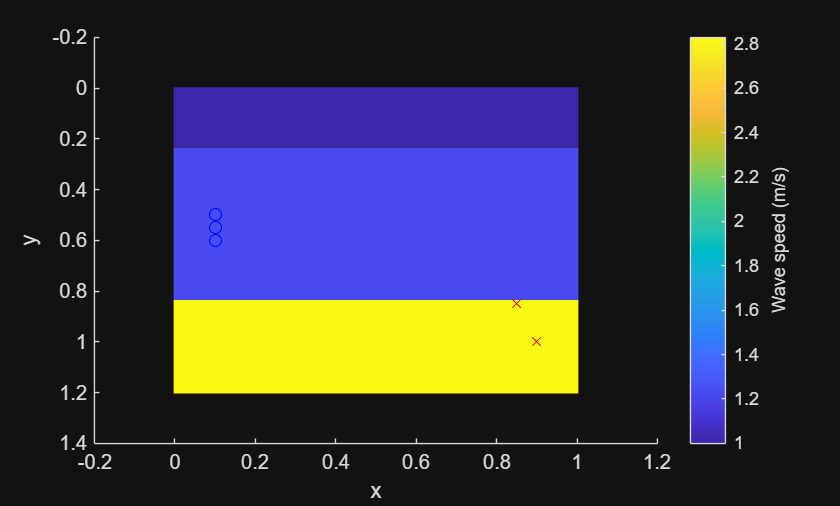

gridSp_y_line = GridSpace2D(grid_x_pt,grid_y_line);

plotAcqGeo(wspeed,mps,gridSp_y_line);
ax = gca;
ax.YDir = "reverse";


% Initialize solver
solver_y_line = AcousticSolver2D_PML( ...
    gridSp_P,t_pts, ...
    gridSp_y_line,t_pts_out, ...
    medium,pml, ...
    SpatialOrder=4);

% Run solver
[P_y_line,~,~] = solver_y_line.solve(p0,vx0,vy0,Source=source);

% Plotting results
ax = axes(figure);
P_y_line.plotTimeSeries(Parent=ax);
ax.CLim = [-0.5,0.5];

Here we specify a grid of receivers.

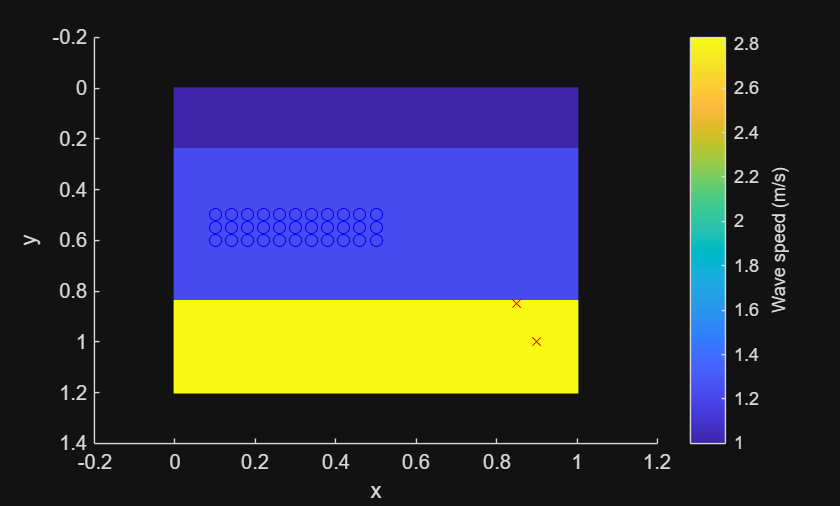

gridSp_grid = GridSpace2D(grid_x_line,grid_y_line);

plotAcqGeo(wspeed,mps,gridSp_grid);
ax = gca;
ax.YDir = "reverse";


% Initialize solver
solver_grid = AcousticSolver2D_PML( ...
    gridSp_P,t_pts, ...
    gridSp_grid,t_pts_out, ...
    medium,pml, ...
    SpatialOrder=4);

% Run solver
[P_grid,~,~] = solver_grid.solve(p0,vx0,vy0,Source=source);


Time series is still visualized as time versus receiver index for a grid of receivers. Note that the indexing of receivers is horizontal major.

P_grid.plotTimeSeries;